# Debugging case 1 kinematics

% add folders to path and load data
addpath 'Data'\ 'Utility Functions'\; % 'Live Scripts'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

##  Investigations on system inconcistencies arising from symbolic pseudoinversion of overconstrained matrices

The local connection from the pfaffian constraint is computed as follows,


$$$ \left( 0 \right)^{4 \times 1} = \left[ \begin{array}{cc} \omega_1^{4 \times 3} & \omega_2^{4 \times 3} \end{array} \right] \left[ \begin{array}{c} \xi \\ \dot{\alpha}  \end{array} \right] $$$



$$\xi = - \omega_1^+ \omega_2 \, \dot{\alpha}$$


where $\omega_1^+$ is the pseudoinverse of $\omega_1$ which is an overdetermined matrix with 4 rows and 3 columns. 

The backslash command in Matlab doesn't seem to work and calls this matrix *inconcistent*. We shall try to explore this in this section.

sympref('AbbreviateOutput', false);
syms a l alpha_1 alpha_2 real
assume(alpha_1 ~= 0); assume(alpha_2 ~= 0);
omega_1 = pfaff_12(:,1:3)

$$omega\_1 = \left(\begin{array}{ccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\\ \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) \end{array}\right)$$

rref(omega_1) % has full column rank! Hence, we should be able to pseudoinvert this without any issue

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0 \end{array}\right)$$

Let's compute the pseudoinverse manually (automated pinv command doesn't work due to division by zero at singularities of the system),

simplify(transpose(omega_1)*omega_1)

$$ans = \left(\begin{array}{ccc} 2 & 0 & -l\,\left(a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{2}\right)+2\right)\\ 0 & 2 & a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)\\ -l\,\left(a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{2}\right)+2\right) & a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right) & 2\,l^{2}\,\left(a\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{2}\right)+a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{2}\right)+a^{2}+2\right) \end{array}\right)$$

simplify(inv(transpose(omega_1)*omega_1))

% omega_1__plus1 = simplify(pinv(transpose(omega_1)*omega_1)*transpose(omega_1))                % using pinv command to compute omega_1__plus -- INFINITE TIME TO RUN
omega_1__plus2 = simplify((transpose(omega_1)*omega_1)\transpose(omega_1))                      % using backslash command

omega_1__plus3 = simplify(inv(transpose(omega_1)*omega_1)*transpose(omega_1))                 % using inv command (on purpose ignoring the warning asking us to use backslash)

% isAlways(omega_1__plus1 == omega_1__plus2)                                        
isAlways(omega_1__plus2 == omega_1__plus3)                                        % check if these two are equal; if they are equal, then we can't expect to see anything different with the pinv or inv command

ans = 3×4 logical array
   1   1   1   1
   1   1   1   1
   1   1   1   1


% also, through these checks we know that we can't expect anything different from writing our local connection computations differently
% removed the first check since pinv basically takes infinite time to run
omega_1__plus = omega_1__plus2;

Seems like the backslash command and inv command give the same output-- hence, let's use the backslash as our standard version for now. 

% % Save data-- UNCOMMENT ONLY IF YOU MADE CHANGES AND WANT TO SAVE NEW VARS; DONT REMOVE THE APPEND COMMAND
% save('Data\case_1_kinematics.mat', 'omega_1__plus', '-append');

% add folders to path and load data
addpath 'Data'\ 'Utility Functions'\; % 'Live Scripts'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

Let's do some more additional checks to see if everything behaves in an expected fashion.

syms a l alpha_1 alpha_2 real
dz_phiO = kin.dz_phi{1}

dz_phiM = simplify(-A_1_12(:,1:2)*kin.dphi_12n, 'Steps', 50)

Check if these two quantities are equal.

isAlways(dz_phiO == dz_phiM)

ans = 3×1 logical array
   1
   1
   1


The computation checks out!

% add folders to path and load data
addpath 'Data'\ 'Utility Functions'\; % 'Live Scripts'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

% Let's check if there is a pullback issue with the integration scheme


% add folders to path and load data
addpath 'Data'\ 'Utility Functions'\; % 'Live Scripts'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

### Numerics vs Symbolic computation

Next, the questions is will the numerics match up if values are substituted before and after the symbolic computation. Let's also do this over the grid of points we used in the kinematics compute function.

The version where we compute the "**numeric pfaffian over the grid" will be the ground truth** since the most of these functions are designed to deal with the numerical values and most symbolic toolboxes (including MATLAB is relatively still in its infancy).

% initialize vars
syms a l alpha_1 alpha_2 real

% first submanifold
si = 1;

% load the shape-space discretization data and functionally computed local connection sweeps
a1 = p_kin{si}.ai; a2 = p_kin{1}.aj;
A__x_1_sweep = p_kin{si}.A__x_1_sweep;
A__x_2_sweep = p_kin{si}.A__x_2_sweep;
A__y_1_sweep = p_kin{si}.A__y_1_sweep;
A__y_2_sweep = p_kin{si}.A__y_2_sweep;
A__theta_1_sweep = p_kin{si}.A__theta_1_sweep;
A__theta_2_sweep = p_kin{si}.A__theta_2_sweep;

% number of points to skip in each direction while displaying a vecF in a 101x101 grid
skp = 10;
idxQ = 1:skp:size(a1,1);

% load and create a pfaffian constraint function
pfaff_12F = matlabFunction(pfaff_12(:,1:5), 'Vars', [a l alpha_1 alpha_2]);

% initialize sweep containers for the numeric case
A__x_1_Nsweep = nan(size(a1));
A__x_2_Nsweep = nan(size(a1));
A__y_1_Nsweep = nan(size(a1));
A__y_2_Nsweep = nan(size(a1));
A__theta_1_Nsweep = nan(size(a1));
A__theta_2_Nsweep = nan(size(a1)); % numeric case


% iterate and compute the function and numeric versions of the local connection, the numerical version will be the ground truth
for k = 1:numel(a1)
    
    % compute the pfaffian constraint
    pfaff_temp = pfaff_12F(1, 1, a1(k), a2(k));

    % compute the connection
    conn_temp = pfaff_temp(:,1:3)\pfaff_temp(:,4:end);

    % assign values to each component
    A__x_1_Nsweep(k) = conn_temp(1,1);
    A__x_2_Nsweep(k) = conn_temp(1,2);
    A__y_1_Nsweep(k) = conn_temp(2,1);
    A__y_2_Nsweep(k) = conn_temp(2,2);
    A__theta_1_Nsweep(k) = conn_temp(3,1);
    A__theta_2_Nsweep(k) = conn_temp(3,2);

end

Now, we can plot out the connection and see if things lineup!

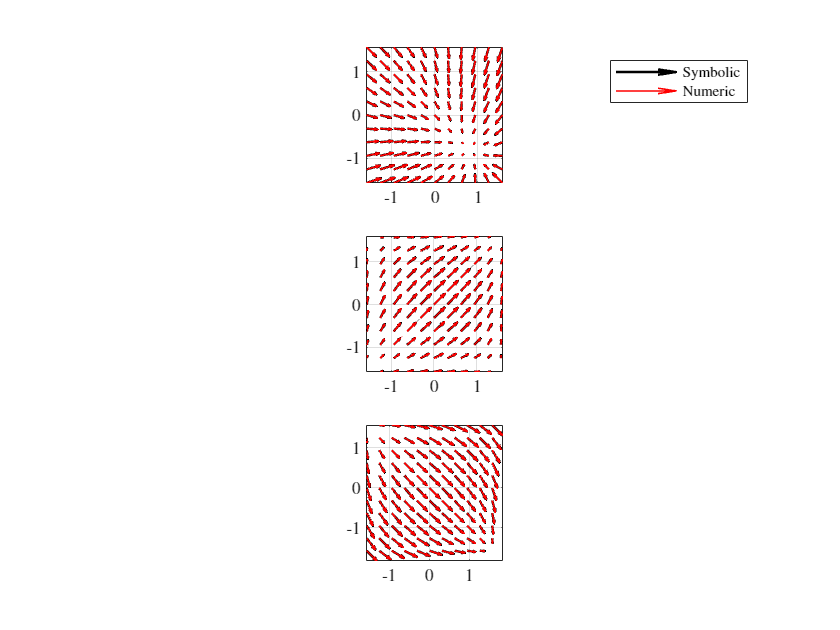

figure()
subplot(3,1,1)
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__x_1_sweep(idxQ, idxQ), A__x_2_sweep(idxQ, idxQ), 'LineWidth', 1.2, 'Color', 'k', 'DisplayName', 'Symbolic');
hold on; grid on; axis equal square tight;
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__x_1_Nsweep(idxQ, idxQ), A__x_2_Nsweep(idxQ, idxQ), 'LineWidth', 0.8, 'Color', 'r', 'DisplayName', 'Numeric');
legend('location','best');

subplot(3,1,2)
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__y_1_sweep(idxQ, idxQ), A__y_2_sweep(idxQ, idxQ), 'LineWidth', 1.2, 'Color', 'k');
hold on; grid on; axis equal square tight;
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__y_1_Nsweep(idxQ, idxQ), A__y_2_Nsweep(idxQ, idxQ), 'LineWidth', 0.8, 'Color', 'r');

subplot(3,1,3)
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__theta_1_sweep(idxQ, idxQ), A__theta_2_sweep(idxQ, idxQ), 'LineWidth', 1.2, 'Color', 'k');
hold on; grid on; axis equal square tight;
quiver(a1(idxQ, idxQ), a2(idxQ, idxQ), A__theta_1_Nsweep(idxQ, idxQ), A__theta_2_Nsweep(idxQ, idxQ), 'LineWidth', 0.8, 'Color', 'r');

There is no difference between the numerical values and the symbolically derived values.

% add folders to path and load data
addpath 'Data'\ 'Utility Functions'\; % 'Live Scripts'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

## Figuring out the local connection

### A weaker constraint of making the relative velocity 0

Here, let's just impose that the feet should have 0 relative velocity.

sympref('AbbreviateOutput', false);
C*J_1_full

$$ans = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & 0 & 0 & 0 \end{array}\right)$$

C*J_2_full

$$ans = \left(\begin{array}{ccccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & a\,l & 0 & 0 \end{array}\right)$$

pfaff_12w = simplify(C*(J_1_full - J_2_full))

$$pfaff\_12w = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & \sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\left(\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & 0 & 0 & 0\\ \sin\left(\alpha_{2}\right)-\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)+l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & -a\,l & 0 & 0 \end{array}\right)$$

simplify(rref(pfaff_12w(:,1:3)))

$$ans = \left(\begin{array}{ccc} 1 & 0 & \frac{l\,\left(\sin\left(\alpha_{1}-\alpha_{2}\right)-\cos\left(\alpha_{1}-\alpha_{2}\right)+a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{2}\right)+1\right)}{\cos\left(\alpha_{1}-\alpha_{2}\right)-1}\\ 0 & 1 & -\frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{\cos\left(\alpha_{1}-\alpha_{2}\right)-1} \end{array}\right)$$

A_12w = simplify(pfaff_12w(:,1:3)\pfaff_12w(:,4:end))

$$A\_12w = \left(\begin{array}{cccc} \frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & -\frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & 0 & 0\\ -\frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & \frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Let's also show the old connection for comparison,

A_1_12

This solution is not unique, looks very different from our old formulation, and we have no solution for rotation. Hence, maybe we can try adding this to the previous formulation we have.

pfaff_12

$$pfaff\_12 = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & 0 & 0 & 0\\ \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & a\,l & 0 & 0 \end{array}\right)$$

pfaff_12r = [ pfaff_12; pfaff_12w ]

$$pfaff\_12r = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & 0 & 0 & 0\\ \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & a\,l & 0 & 0\\ \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & \sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\left(\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & 0 & 0 & 0\\ \sin\left(\alpha_{2}\right)-\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)+l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & -a\,l & 0 & 0 \end{array}\right)$$

A_12r = pfaff_12r(:,1:3)\pfaff_12r(:,4:end)

$$A\_12r = \left(\begin{array}{cccc} \infty & \infty & \infty & \infty \\ \infty & \infty & \infty & \infty \\ \infty & \infty & \infty & \infty \end{array}\right)$$

% save data
if exist('Data\debug_case_1_kinematics.mat','file') == 2 % if the file already exists, just append
    save('Data\debug_case_1_kinematics', 'pfaff_12w', 'A_12w', '-append');
else
    save('Data\debug_case_1_kinematics', 'pfaff_12w', 'A_12w');
end

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

### Using our $k^2$ obtain orientation and using that in our old connection

Consider $S_{12}$ for and example,

sympref('AbbreviateOutput', false);
syms a l alpha_1 alpha_2 real

Let's display the old connection $A_{12}$ for reference,

A_1_12

k_12 = C*(h_b__2 - h_b__1)

$$k\_12 = \left(\begin{array}{c} -l\,\left(a\,\cos\left(\alpha_{1}\right)+1\right)-l\,\left(a\,\cos\left(\alpha_{2}\right)+1\right)\\ -l\,\left(a\,\sin\left(\alpha_{1}\right)+1\right)-l\,\left(a\,\sin\left(\alpha_{2}\right)-1\right) \end{array}\right)$$

Say the orientation of this vector is $
{}^k \theta = \tan^{-1} \frac{k_y}{k_x}$,

ktheta = atan( k_12(2), k_12(1) )

$$ktheta = \text{atan2}\left(-l\,\left(a\,\sin\left(\alpha_{1}\right)+1\right)-l\,\left(a\,\sin\left(\alpha_{2}\right)-1\right),-l\,\left(a\,\cos\left(\alpha_{1}\right)+1\right)-l\,\left(a\,\cos\left(\alpha_{2}\right)+1\right)\right)$$

simplify( diff(ktheta, alpha_1) )

$$ans = \frac{a\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4}$$

simplify( diff(ktheta, alpha_2) )

$$ans = \frac{a\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4}$$

Ahh!! This is where we see the difference in formulation! Let's now obtain a connection through this method.

Note that the rate of change of $
{}^k \theta$ is obtained by taking its gradient in the shape-space,


$$\nabla \, {}^k \theta_{ij} = \left( \begin{array}{cc} \frac{\partial \, {}^k \theta}{\partial \alpha_i} & \frac{\partial \, {}^k \theta}{\partial \alpha_j} \end{array} \right)$$


dktheta = [ simplify( diff(ktheta, alpha_1) ) simplify( diff(ktheta, alpha_2) ) ]

$$dktheta = \left(\begin{array}{cc} \frac{a\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{a\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

Now, I contend that in order to hold the orientation of this vector throughout the $S_{12}$ contact state, the body rotation needs to happen in the opposite direction,


$$\left[ -\mathbf{A}^{\theta} \right]_{ij} = -\nabla \, {}^k \theta_{ij}$$


dtheta = -dktheta; 
A_12F__theta = dktheta; % also substitute by negating the sign (-A gives the right direction)

Then, we can use this to construct the translation part of the local connection, $-\mathbf{A}^{xy}$ by simplifying the pfaffian constraint as follows,


$$\left( \begin{array}{ccccc} \omega_x & \omega_y & \omega_\theta & \omega_i & \omega_j \end{array} \right) \left( \begin{array}{c} dx \\ dy \\ d\theta \\ d{\alpha}_i \\ d{\alpha}_j \end{array} \right) = 0$$


Separate this out, and rewrite the constraint system of equations as follows


$$\left( \begin{array}{ccccc} \omega_x & \omega_y & \left( -\omega_\theta \,\, \nabla {}^k \theta_{ij} \right)_1 + \omega_i & \left( -\omega_\theta \,\, \nabla {}^k \theta_{ij} \right)_2 + \omega_j \end{array} \right) \left( \begin{array}{c} dx \\ dy \\ d{\alpha}_i \\ d{\alpha}_j \end{array} \right) = 0$$


where $\left( -\omega_\theta \,\, \nabla {}^k \theta_{ij} \right)_1$ is the first column of the product $-\omega_\theta \,\, \nabla {}^k \theta_{ij}$ which corresponds to the change in orientation contribution from swining leg i.

Pseudo-inversion of this pfaffian constraint is expected to give the correct local connection. Let's try that out!

pfaff_12F = simplify([ pfaff_12(:,1), pfaff_12(:,2), ( pfaff_12(:,3)*dtheta + [ pfaff_12(:,4) pfaff_12(:,5) ] ), pfaff_12(:,6:end) ])

% A_12F__xy = simplify(pfaff_12F(:,1:2)\pfaff_12F(:,3:end)) % backslash command still doesn't work, let's try pseudoinversion
A_12F__xy = simplify( (transpose(pfaff_12F(:,1:2))*pfaff_12F(:,1:2))\transpose(pfaff_12F(:,1:2)) * pfaff_12F(:,3:end) );

Get the full connection,

A_12F = [ A_12F__xy; [A_12F__theta, 0, 0] ]

Display the old connection for comparison,

A_1_12

Let's do a full sign comparison below; because on the first glance, the terms seem to be similar, but the signs are different.

simplify(A_12F(:,1:2)./A_1_12(:,1:2))

$$ans = \left(\begin{array}{cc} 1 & -\frac{4\,a+8\,\cos\left(\alpha_{2}\right)-8\,\sin\left(\alpha_{2}\right)+3\,a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+6\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)-6\,a\,\sin\left(2\,\alpha_{2}\right)-a^{2}\,\sin\left(\alpha_{1}\right)-5\,a^{2}\,\sin\left(\alpha_{2}\right)}{4\,a+8\,\cos\left(\alpha_{2}\right)+8\,\sin\left(\alpha_{2}\right)-a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)+6\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\sin\left(2\,\alpha_{2}\right)+3\,a^{2}\,\sin\left(\alpha_{1}\right)+3\,a^{2}\,\sin\left(\alpha_{2}\right)}\\ 1 & \frac{6\,a+8\,\cos\left(\alpha_{2}\right)+3\,a^{2}\,\cos\left(\alpha_{1}-2\,\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}+\alpha_{2}\right)-a^{2}\,\cos\left(2\,\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+6\,a\,\cos\left(2\,\alpha_{2}\right)+a^{2}\,\cos\left(\alpha_{1}\right)+5\,a^{2}\,\cos\left(\alpha_{2}\right)}{2\,a+8\,\cos\left(\alpha_{2}\right)+a^{2}\,\cos\left(\alpha_{1}-2\,\alpha_{2}\right)+6\,a\,\cos\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\cos\left(2\,\alpha_{1}-\alpha_{2}\right)+6\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(2\,\alpha_{2}\right)+3\,a^{2}\,\cos\left(\alpha_{1}\right)+3\,a^{2}\,\cos\left(\alpha_{2}\right)}\\ 1 & -1 \end{array}\right)$$

From what we see, the first column matches $\mathbf{A}_1 = {}^k \mathbf{A}_1$, the second column translation doesn't, and the $(3,2)$ term is in the negative direction. We need to probe this further to recognize what's going on.

if exist('Data\debug_case_1_kinematics.mat','file') == 2 % if the file already exists, just append
    save('Data\debug_case_1_kinematics', 'A_12F', 'A_12F__theta', 'dtheta', '-append');
else
    save('Data\debug_case_1_kinematics', 'A_12F', 'A_12F__theta', 'dtheta');
end

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

### Stratified Panels (using different constraints)

Let's test this out by developing the stratified panels and taking things from there.

dphi_unit = kin.dphi_ij{1}/norm(kin.dphi_ij{1});

The old stratified panels

dz_12 = kin.dz_phi{1}

dz_12F = simplify(-A_12F(:,1:2)*dphi_unit, 'Steps', 50)

save('Data\debug_case_1_kinematics', 'dz_12F', 'dphi_unit', '-append');

Animations are done at the end of "se2_toyproblems_case_1.mlx".

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

Let's obtain a slightly weaker form of the complete connection with some equations we obtained in the previous section.

A_12w

$$A\_12w = \left(\begin{array}{cccc} \frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & -\frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & 0 & 0\\ -\frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & \frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

A_12F__theta

$$A\_12F\_\_theta = \left(\begin{array}{cc} \frac{a\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{a\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

Let's combine these two to make the weaker local connection based on the scalar field $k^2_{12}$.

A_12Fw = [ A_12w(1:2,1:2);  A_12F__theta ]

$$A\_12Fw = \left(\begin{array}{cc} \frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & -\frac{a\,l\,\left(\sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)}\\ -\frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)} & \frac{a\,l\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{2\,\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)}\\ \frac{a\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{a\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

Get the associated stratified panel and save the results.

dz_12Fw = simplify(-A_12Fw*dphi_unit, 'Steps', 50)

$$dz\_12Fw = \left(\begin{array}{c} \frac{a^{2}\,l\,\left({\sin\left(\alpha_{1}\right)}^{2}-{\sin\left(\alpha_{2}\right)}^{2}\right)}{\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)\,\sqrt{{\left(a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{2}\right)\right)}^{2}+a^{2}\,{\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}^{2}}}\\ -\frac{a^{2}\,l\,\left(\sin\left(\alpha_{1}\right)+\sin\left(\alpha_{2}\right)\right)\,\left(\cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right)\right)}{\left(\cos\left(\alpha_{1}-\alpha_{2}\right)-1\right)\,\sqrt{{\left(a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{2}\right)\right)}^{2}+a^{2}\,{\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}^{2}}}\\ -\frac{a^{2}\,\left(2\,\sin\left(\alpha_{1}-\alpha_{2}\right)+a\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)+a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)+\frac{a^{2}\,\sin\left(2\,\alpha_{1}-2\,\alpha_{2}\right)}{2}+a\,\sin\left(\alpha_{1}\right)-a\,\sin\left(\alpha_{2}\right)+a\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)\right)}{\sqrt{{\left(a^{2}\,\sin\left(\alpha_{1}-\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{2}\right)\right)}^{2}+a^{2}\,{\left(2\,\sin\left(\alpha_{1}\right)+a\,\sin\left(\alpha_{1}-\alpha_{2}\right)\right)}^{2}}\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} \end{array}\right)$$

save('Data\debug_case_1_kinematics','dz_12Fw','-append');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

Let's try the weaker connection, but by using the theta connection we computed earier.

pfaff_12w

$$pfaff\_12w = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & \sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\left(\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & 0 & 0 & 0\\ \sin\left(\alpha_{2}\right)-\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)+l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & -a\,l & 0 & 0 \end{array}\right)$$

Let's use our orientation knowledge to combine column 3 with columns 4 and 5 as shown below,


$$\left( \begin{array}{ccccc} \omega_x & \omega_y & \omega_\theta & \omega_i & \omega_j \end{array} \right) \left( \begin{array}{c} dx \\ dy \\ d\theta \\ d{\alpha}_i \\ d{\alpha}_j \end{array} \right) = 0$$



$$\Rightarrow \left( \begin{array}{ccccc} \omega_x & \omega_y & \left( -\omega_\theta \,\, \nabla {}^k \theta_{ij} \right)_1 + \omega_i & \left( -\omega_\theta \,\, \nabla {}^k \theta_{ij} \right)_2 + \omega_j \end{array} \right) \left( \begin{array}{c} dx \\ dy \\ d{\alpha}_i \\ d{\alpha}_j \end{array} \right) = 0$$


pfaff_12_FW = simplify( [ pfaff_12w(:,1), pfaff_12w(:,2), ( pfaff_12w(:,3)*dtheta + [ pfaff_12w(:,4) pfaff_12w(:,5) ] ) ], 'Steps', 10 )

$$pfaff\_12\_FW = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & \sin\left(\alpha_{1}\right)-\sin\left(\alpha_{2}\right) & \frac{\sqrt{2}\,a\,l\,\left(\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{\sqrt{2}\,a\,l\,\left(\cos\left(\alpha_{1}+\frac{\pi }{4}\right)-\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4}\\ \sin\left(\alpha_{2}\right)-\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right)-\cos\left(\alpha_{2}\right) & a\,l-\frac{a\,l\,\left(2\,a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & -a\,l-\frac{a\,l\,\left(2\,a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

A_12xy = simplify( pfaff_12_FW(:,1:2)\pfaff_12_FW(:,3:end), 'Steps', 10 )

A_12theta = -dtheta;
A_12_FW = [ A_12xy; A_12theta ]

The corresponding stratified panel,

dz_12_FW = simplify( -A_12_FW*dphi_unit, 'Steps', 50 )

save('Data\debug_case_1_kinematics','dz_12_FW','-append');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

Here, we shall try the averaged connection method-- separately pseudoinvert and obtain the connection for each leg.

pfaff_1 = C*J_1_full

$$pfaff\_1 = \left(\begin{array}{ccccccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & -\sqrt{2}\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right) & a\,l & 0 & 0 & 0 \end{array}\right)$$

pfaff_2 = C*J_2_full

$$pfaff\_2 = \left(\begin{array}{ccccccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & -\sqrt{2}\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right) & 0 & 0 & 0 & 0\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & -l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right) & 0 & a\,l & 0 & 0 \end{array}\right)$$

Modify with our theta connection,

pfaff_1_F = simplify( [ pfaff_1(:,1), pfaff_1(:,2), ( pfaff_1(:,3)*dtheta + [ pfaff_1(:,4) pfaff_1(:,5) ] ) ], 'Steps', 10 )

$$pfaff\_1\_F = \left(\begin{array}{cccc} \cos\left(\alpha_{1}\right) & \sin\left(\alpha_{1}\right) & \frac{\sqrt{2}\,a\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{\sqrt{2}\,a\,l\,\cos\left(\alpha_{1}+\frac{\pi }{4}\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4}\\ -\sin\left(\alpha_{1}\right) & \cos\left(\alpha_{1}\right) & a\,l-\frac{a\,l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & -\frac{a\,l\,\left(a+\sqrt{2}\,\sin\left(\alpha_{1}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

pfaff_2_F = simplify( [ pfaff_2(:,1), pfaff_2(:,2), ( pfaff_2(:,3)*dtheta + [ pfaff_2(:,4) pfaff_2(:,5) ] ) ], 'Steps', 10 )

$$pfaff\_2\_F = \left(\begin{array}{cccc} \cos\left(\alpha_{2}\right) & \sin\left(\alpha_{2}\right) & \frac{\sqrt{2}\,a\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & \frac{\sqrt{2}\,a\,l\,\sin\left(\alpha_{2}+\frac{\pi }{4}\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4}\\ -\sin\left(\alpha_{2}\right) & \cos\left(\alpha_{2}\right) & \frac{a\,l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} & a\,l+\frac{a\,l\,\left(a+\sqrt{2}\,\cos\left(\alpha_{2}+\frac{\pi }{4}\right)\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{2}\right)+2\,a^{2}+4} \end{array}\right)$$

A_12_1xy_F = simplify( pfaff_1_F(:,1:2)\pfaff_1_F(:,3:4), 'Steps', 10 )

$$A\_12\_1xy\_F = \left(\begin{array}{cc} -\frac{a\,l\,\left(8\,\sin\left(\alpha_{1}\right)-4\,\cos\left(\alpha_{1}\right)-2\,a+4\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)-2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\sin\left(2\,\alpha_{1}\right)+2\,a^{2}\,\sin\left(\alpha_{1}\right)+a^{2}\,\sin\left(\alpha_{2}\right)\right)}{4\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} & \frac{a\,l\,\left(2\,a+4\,\cos\left(\alpha_{2}\right)+2\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\sin\left(2\,\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)+2\,a^{2}\,\sin\left(\alpha_{1}\right)+a^{2}\,\sin\left(\alpha_{2}\right)\right)}{4\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)}\\ \frac{a\,l\,\left(4\,\cos\left(\alpha_{1}\right)+4\,a\,\cos\left(\alpha_{1}+\alpha_{2}\right)+a^{2}\,\cos\left(2\,\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(2\,\alpha_{1}\right)+2\,a^{2}\,\cos\left(\alpha_{1}\right)+a^{2}\,\cos\left(\alpha_{2}\right)\right)}{4\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} & -\frac{a\,l\,\left(a\,\cos\left(\alpha_{1}\right)+1\right)\,\left(a+2\,\cos\left(\alpha_{2}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} \end{array}\right)$$

A_12_2xy_F = simplify( pfaff_2_F(:,1:2)\pfaff_2_F(:,3:4), 'Steps', 10 )

$$A\_12\_2xy\_F = \left(\begin{array}{cc} \frac{a\,l\,\left(2\,a+4\,\cos\left(\alpha_{1}\right)+a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)-2\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)-a^{2}\,\sin\left(\alpha_{1}\right)-2\,a^{2}\,\sin\left(\alpha_{2}\right)\right)}{4\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} & \frac{a\,l\,\left(2\,a+4\,\cos\left(\alpha_{2}\right)-8\,\sin\left(\alpha_{2}\right)+3\,a^{2}\,\sin\left(\alpha_{1}-2\,\alpha_{2}\right)-4\,a\,\sin\left(\alpha_{1}+\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+4\,a\,\sin\left(\alpha_{1}-\alpha_{2}\right)-6\,a\,\sin\left(2\,\alpha_{2}\right)-3\,a^{2}\,\sin\left(\alpha_{1}\right)-6\,a^{2}\,\sin\left(\alpha_{2}\right)\right)}{4\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)}\\ \frac{a\,l\,\left(a\,\cos\left(\alpha_{2}\right)+1\right)\,\left(a+2\,\cos\left(\alpha_{1}\right)+a\,\cos\left(\alpha_{1}-\alpha_{2}\right)\right)}{2\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} & \frac{a\,l\,\left(4\,a+6\,\cos\left(\alpha_{2}\right)+\frac{3\,a^{2}\,\cos\left(\alpha_{1}-2\,\alpha_{2}\right)}{2}+2\,a\,\cos\left(\alpha_{1}+\alpha_{2}\right)+3\,a\,\cos\left(\alpha_{1}-\alpha_{2}\right)+3\,a\,\cos\left(2\,\alpha_{2}\right)+\frac{3\,a^{2}\,\cos\left(\alpha_{1}\right)}{2}+3\,a^{2}\,\cos\left(\alpha_{2}\right)\right)}{2\,\left(a^{2}\,\cos\left(\alpha_{1}-\alpha_{2}\right)+2\,a\,\cos\left(\alpha_{1}\right)+2\,a\,\cos\left(\alpha_{2}\right)+a^{2}+2\right)} \end{array}\right)$$

Okay, now we contend that these two connections are the same and hence, let's average them to find the mean local connection for translational velocities.

A_12xy_Fm = simplify( (A_12_1xy_F + A_12_2xy_F)/2, 'Steps', 10 )

Get the completed mean connection, and the corresponding stratified panel.

A_12_Fm = [ A_12xy_Fm; -dtheta ]

dz_12_Fm = simplify( -A_12_Fm*dphi_unit, 'Steps', 50 )

save('Data\debug_case_1_kinematics','dz_12_Fm','-append');

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

Let's just try two more cases where we just negate the x and y-columns in the original connection.

A_12mY = A_1_12; 
A_12mY(:,2) = -A_12mY(:,2); % negate the second column
A_12mY = A_12mY(:,1:2) % remove the other columns

dz_12mY = simplify( -A_12mY*dphi_unit, 'Steps', 50 )

save('Data\debug_case_1_kinematics','A_12mY','dz_12mY','-append');
A_12mX = A_1_12; 
A_12mX(:,1) = -A_12mX(:,1); % negate the second column
A_12mX = A_12mX(:,1:2) % remove the other columns

dz_12mX = simplify( -A_12mX*dphi_unit, 'Steps', 50 )

save('Data\debug_case_1_kinematics','A_12mX','dz_12mX','-append');

UPDATE 2023/02/06: The jth column of the local connection has the incorrect sign (this happens for $S_{12}$, but we need to verify this for other submanifolds)-- occurs from the incorrect transform for legs on the left side of the body.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat'); load('Data\debug_case_1_kinematics');

Verifying that fixing the transforms worked.

A_1_12(:,1:2)

A_12mY

isAlways( A_12mY == A_1_12(:,1:2) )

ans = 3×2 logical array
   1   0
   1   0
   1   0


Proves that they are equal!!! xD